clc

StrainInd = flip(PDMS1Indentation.VarName1)

StrainInd =     0.1548
    0.1611
    0.1797
    0.1970
    0.2171
    0.2399
    0.2586
    0.2704
    0.2898
    0.3133


%XdiffInd = flip(PDMS1Indentation.VarName3)
YdiffInd = flip(PDMS1Indentation.VarName5)

YdiffInd =     0.0779
    0.0744
    0.0728
    0.0776
    0.0718
    0.0786
    0.0802
    0.0728
    0.0792
    0.0760


%SumInd = flip(PDMS1Indentation.VarName7)
StrainRet = flip(PDMS1Retraction.VarName1)

StrainRet =    10.5310
   10.5123
   10.5095
   10.4888
   10.4729
   10.4604
   10.4410
   10.4286
   10.4147
   10.3877


%XdiffRet = flip(PDMS1Retraction.VarName3)
YdiffRet = flip(PDMS1Retraction.VarName5)

YdiffRet =     1.6192
    1.6188
    1.5998
    1.6011
    1.5647
    1.5711
    1.5569
    1.5473
    1.5141
    1.4867


%SumRet = flip(PDMS1Retraction.VarName7)
SpringConst = 0.32;

smooth_Strain = smoothdata(StrainInd)

smooth_Strain =     1.0473
    1.0589
    1.0705
    1.0821
    1.0939
    1.1055
    1.1173
    1.1290
    1.1408
    1.1526


smooth_Ydiff = smoothdata(YdiffInd)

smooth_Ydiff =     0.0765
    0.0765
    0.0766
    0.0764
    0.0763
    0.0763
    0.0763
    0.0764
    0.0764
    0.0764


smooth_RetYdiff = smoothdata(YdiffRet)

smooth_RetYdiff =     1.4360
    1.4252
    1.4150
    1.4043
    1.3931
    1.3820
    1.3707
    1.3592
    1.3482
    1.3364


smooth_RetStrain = smoothdata(StrainRet)

smooth_RetStrain =     9.7124
    9.7015
    9.6905
    9.6795
    9.6685
    9.6575
    9.6465
    9.6354
    9.6242
    9.6131


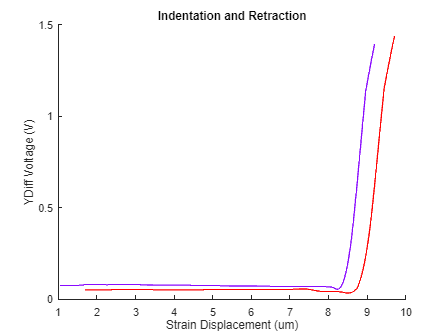


figure
hold on
plot(smooth_Strain, smooth_Ydiff, '-', 'Color', '#890aff')
plot(smooth_RetStrain, smooth_RetYdiff, '-', 'Color', '#FF0000')
title('Indentation and Retraction')
xlabel('Strain Displacement (um)')
ylabel('YDiff Voltage (V)')
hold off


% Plot the data
figure
hold on
plot(smooth_Strain, smooth_Ydiff, '-', 'Color', '#890aff')
xlabel('Strain Displacement (um)')
ylabel('YDiff Voltage (V)')

% Manual Selection of Starting and Ending Points to Curve Fit
title('Start Point Selection')
[startX, ~] = ginput(1)

startX = 8.4758

title('End Point Selection')
[endX, ~] = ginput(1)

endX = 8.9113


% Find indices corresponding to the selected points
startIdx = find(smooth_Strain >= startX, 1, 'first')

startIdx = 334

endIdx = find(smooth_Strain <= endX, 1, 'last')

endIdx = 361


% Curve fit
degree = 1

degree = 1

coeff = polyfit(smooth_Strain(startIdx:endIdx), smooth_Ydiff(startIdx:endIdx), degree)

coeff =     2.0321  -17.1213



% Plot the fitted curve onto the original graph
plot(smooth_Strain, smooth_Ydiff, '-', 'Color', '#890aff')
plot(smooth_Strain(startIdx:endIdx), smooth_Ydiff(startIdx:endIdx), 'o', 'MarkerSize', 10, 'Color', 'r')
fittedcurve = polyval(coeff, smooth_Strain(startIdx:endIdx))

fittedcurve =     0.1332
    0.1644
    0.1955
    0.2266
    0.2574
    0.2884
    0.3194
    0.3505
    0.3815
    0.4127


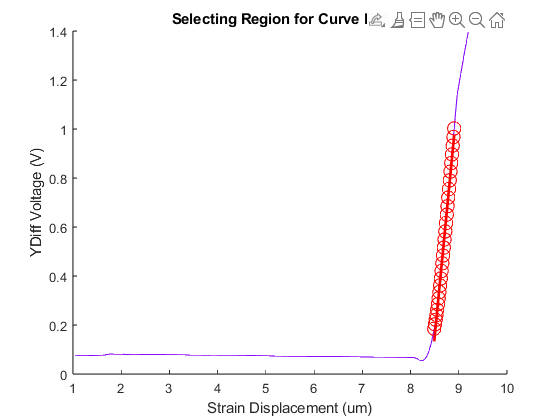

plot(smooth_Strain(startIdx:endIdx), fittedcurve, 'r', 'LineWidth', 2)
title('Selecting Region for Curve Fitting')
xlabel('Strain Displacement (um)')
ylabel('YDiff Voltage (V)')
hold off


%Identify Point of Contact
%figure
%plot(smooth_Strain(startIdx:endIdx), smooth_Ydiff(startIdx:endIdx), '-', 'Color', '#890aff')
%title('Indentation')
%xlabel('Strain Displacement (um)')
%ylabel('YDiff Voltage (V)')

%slope = coeff(1)

ZeroedX = smooth_Strain(startIdx:endIdx)

ZeroedX =     8.4909
    8.5062
    8.5215
    8.5368
    8.5520
    8.5672
    8.5825
    8.5978
    8.6131
    8.6284


ZeroedX = ZeroedX - smooth_Strain(startIdx)

ZeroedX =          0
    0.0153
    0.0306
    0.0459
    0.0611
    0.0763
    0.0916
    0.1069
    0.1222
    0.1375


ZeroedY = smooth_Ydiff(startIdx:endIdx)

ZeroedY =     0.1847
    0.2025
    0.2213
    0.2409
    0.2621
    0.2851
    0.3090
    0.3345
    0.3617
    0.3901


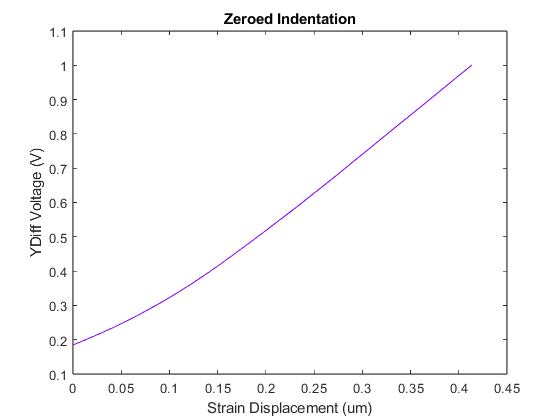


%Indentation Zeroed
plot(ZeroedX, ZeroedY, '-', 'Color', '#890aff')
title('Zeroed Indentation')
xlabel('Strain Displacement (um)')
ylabel('YDiff Voltage (V)')


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Displacement Conversion of Y-axis and Unit Conversion
Height = ZeroedX * 0.000001

Height = 1.0e-06 *

         0
    0.0153
    0.0306
    0.0459
    0.0611
    0.0763
    0.0916
    0.1069
    0.1222
    0.1375


Deflection = (ZeroedY/slope)*0.000001

Deflection = 1.0e-06 *

    0.1132
    0.1242
    0.1357
    0.1478
    0.1607
    0.1748
    0.1895
    0.2051
    0.2218
    0.2392


Indentation = Height - Deflection

Indentation = 1.0e-06 *

   -0.1132
   -0.1088
   -0.1051
   -0.1018
   -0.0996
   -0.0985
   -0.0979
   -0.0982
   -0.0996
   -0.1017


%Convert Deflection into Force
Force = Deflection * SpringConst

Force = 1.0e-06 *

    0.0362
    0.0397
    0.0434
    0.0473
    0.0514
    0.0559
    0.0606
    0.0656
    0.0710
    0.0766



%Indentation Calibrated
figure
hold on
plot(Indentation, Force, '-', 'Color', '#890aff')
title('Indentation')
xlabel('Indentation (m)')
ylabel('Force (N)')

% Manual Selection of Starting and Ending Points to Curve Fit
title('Start Point Selection')
[FitXStart, ~] = ginput(1)

FitXStart = -1.1081e-07

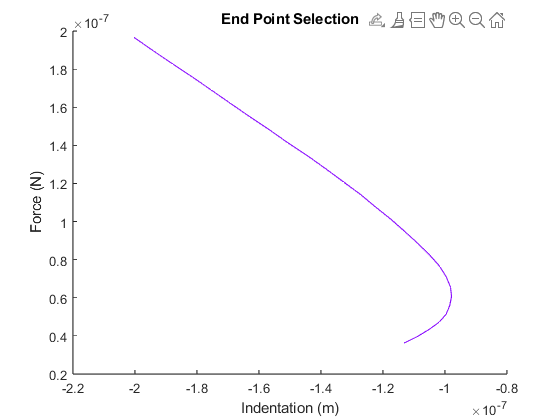

FitXEnd = -1.0016e-07

title('End Point Selection')
[FitXEnd, ~] = ginput(1)


% Find indices corresponding to the selected points
FitstartIdx = find(Indentation >= startX, 1, 'first')


FitstartIdx =

  0×1 empty double column vector



FitendIdx = find(Indentation <= endX, 1, 'last')

FitendIdx = 28